# Import Date and Time Data

Use `DatetimeVariableImportOptions` properties to control the import of `datetime` data. First, get the `ImportOptions` object for the file. Next, examine and update the `VariableImportOptions` for the datetime variables. Finally, import the variables using `readtable`. 

Preview of data in `outages.csv`. Notice the date and time data in the columns `OutageTime` and `RestorationTime`. Only the first 10 rows are shown here. 

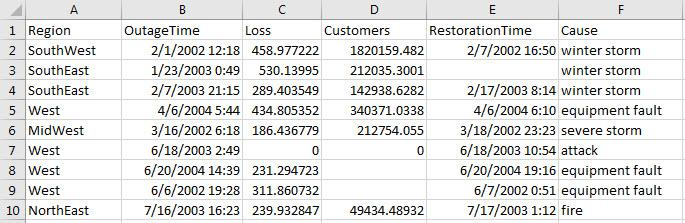

Get the import options object. 

opts = detectImportOptions('outages.csv');

Get and examine the `VariableImportOptions` for datetime variables `OutageTime` and `RestorationTime`.

varOpts = getvaropts(opts,{'OutageTime','RestorationTime'})

Set the `FillValue` property of the variables to replace missing values with current date and time.

opts = setvaropts(opts,{'OutageTime','RestorationTime'},...
                                           'FillValue','now');

Select, read, and preview the two variables. Notice the missing value in the second row of `RestorationTime` has been filled with current date and time.

opts.SelectedVariableNames = {'OutageTime','RestorationTime'};
T = readtable('outages.csv',opts); 
T(1:10,:)

*Copyright 2019 The MathWorks, Inc.*